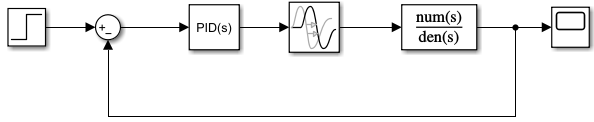

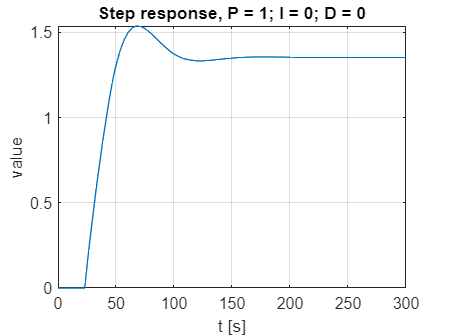

clear;
k = 1.18; tau = 22; T = 45; r = 2.5;

P = 1; I = 0; D = 0;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1; I = 0; D = 0");
xlabel("t [s]");
ylabel("value");
grid on;

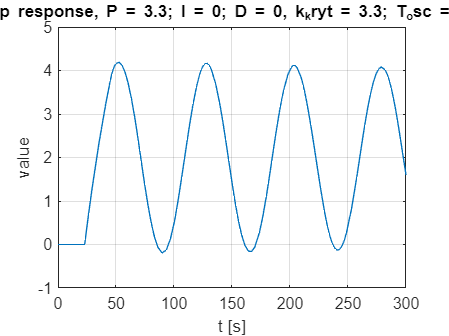

P = 3.3; I = 0; D = 0;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 3.3; I = 0; D = 0, k_kryt = 3.3; T_osc = 75.7");
xlabel("t [s]");
ylabel("value");
grid on;

% [t, y] = ginput(2);
T_osc = 75.7;

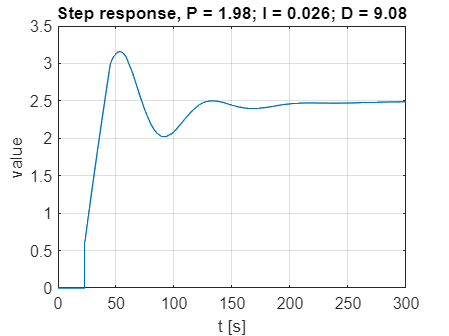

P = 0.6 * 3.3; I = 1 / (0.5 * T_osc); D = 0.12 * T_osc;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.98; I = 0.026; D = 9.08");
xlabel("t [s]");
ylabel("value");
grid on;

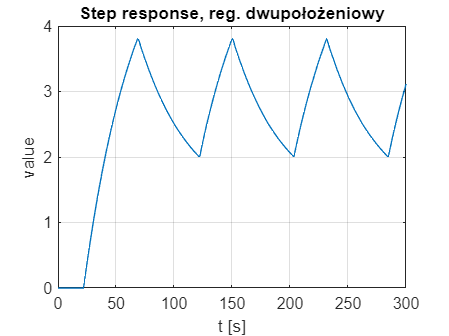

out = sim("PID.slx");
figure;
plot(out.twoPolStepResponse.time, out.twoPolStepResponse.signals.values);
title("Step response, reg. dwupołożeniowy");
xlabel("t [s]");
ylabel("value");
grid on;

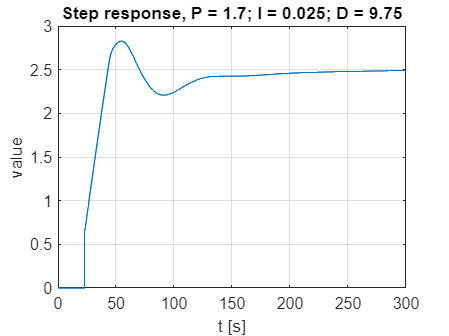


u = 2;
%[t, y] = ginput(2);
A = 1.7944 / 2;
T_osc = 81.2155;
k_kr = 4 * u / (pi * A);
P = 0.6 * k_kr; I = 1 / (0.5 * T_osc); D = 0.12 * T_osc;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.7; I = 0.025; D = 9.75");
xlabel("t [s]");
ylabel("value");
grid on;

Założenie przeregulowania 20%

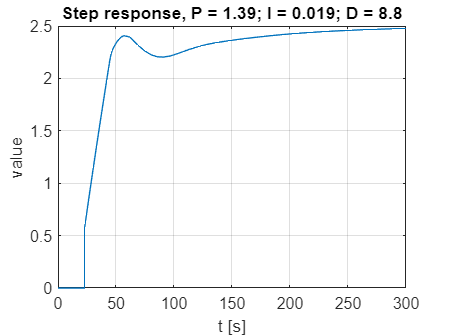

P = k_kr * (tau/T); I = 1 / (2.4 * tau); D = 0.4 * tau;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.019; D = 8.8");
xlabel("t [s]");
ylabel("value");
grid on;

Założenie minimum z całki kwadratu uchybu

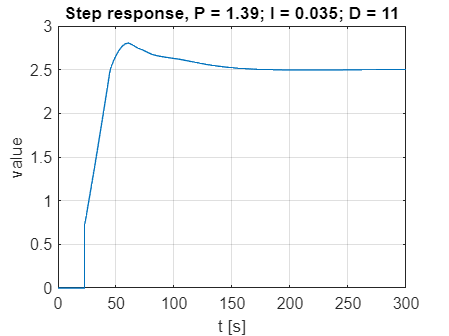

P = k_kr * (tau/T); I = 1 / (1.3 * tau); D = 0.5 * tau;
out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;

Strojenie automatyczne - Eksperyment 1 - brak przeregulowania

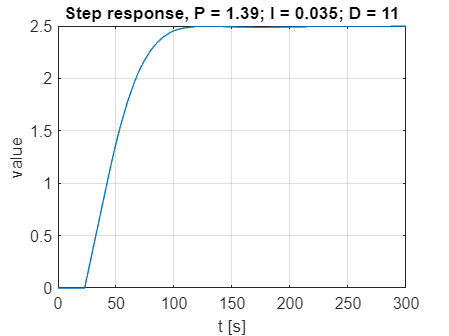

out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;

Strojenie automatyczne - Eksperyment 2 - niewielkie przeregulowanie

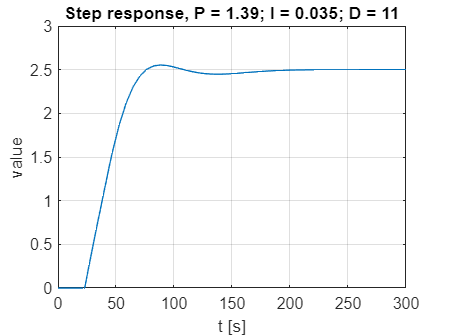

out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;

Strojenie automatyczne - Eksperyment 3 - wolne wysterowanie, brak przeregulowania

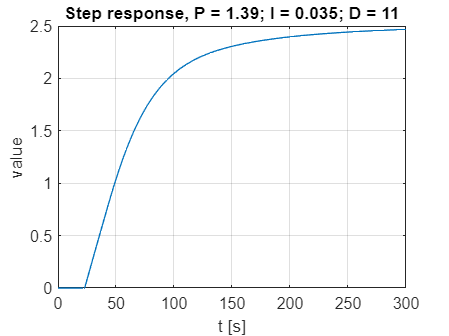

out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;

Strojenie automatyczne - Eksperyment 4 - bardzo szybkie wysterowanie

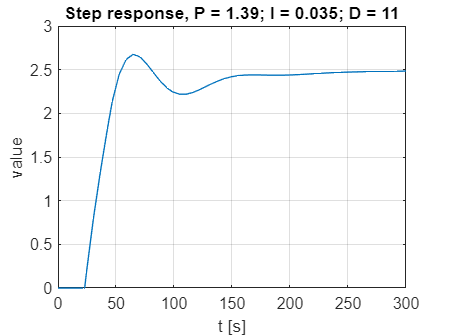

out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;

Strojenie automatyczne - Eksperyment 4 - bardzo szybkie wysterowanie, brak oscylacji

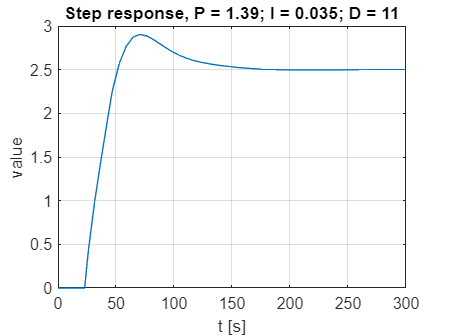

out = sim("PID.slx");
figure;
plot(out.stepResponse.time, out.stepResponse.signals.values);
title("Step response, P = 1.39; I = 0.035; D = 11");
xlabel("t [s]");
ylabel("value");
grid on;